4. Diseñar 4 filtros de 45 coeficientes, cada uno con las frecuencias positivas de corte ideales en

filtro1=$\left\lbrack 0,\frac{\pi }{4}\right\rbrack$

filtro2=$\left\lbrack \frac{\pi }{4},\frac{\pi }{2}\right\rbrack$

filtro3=$\left\lbrack \frac{\pi }{4},\frac{3\pi }{4}\right\rbrack$

filtro4=$\left\lbrack \frac{3\pi }{4},\pi \right\rbrack$

Definimos un tiempo de observacion de 1 seg. Esto quiere decir que si muestreamos a 8000 muestras por segundo tendremos 1/8000 como tiempo de observacion. 

## Radian domain

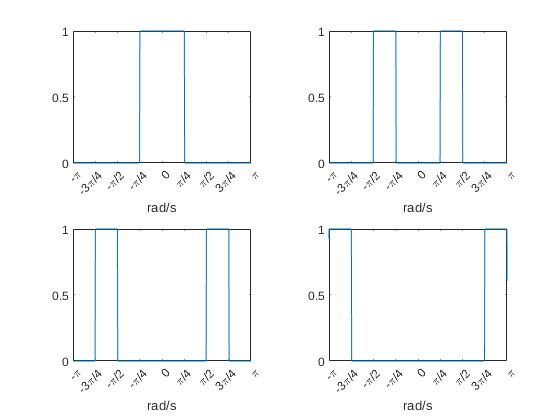

bound =[-pi,pi];
space = bound(1)-1/100:1/100:bound(2)+1/100;
%generate 4 spaces 
rad_space = zeros(4,length(space));
range = 0:pi/4:pi;
% 4 graphs to be ploted
figure(1)
t = tiledlayout(2,2);
side =[-1,1];
for n=2:1:5
    %index in space
    for m=side % negative, positve side
        start_filter = find(space == interp1(space,space,m*range(n-1),'nearest'));
        end_filter   = find(space == interp1(space,space,m*range(n),'nearest'));
        %4d tensor of filters, n-1 acces to layer of tensor. 
        rad_space(n-1,min(start_filter,end_filter):max(start_filter,end_filter)) = 1;
    end
    %plotting stuff
    nexttile
    plot(space,rad_space(n-1,:));
    xlim([-pi pi])
    xticks([-pi -pi*3/4 -pi/2 -pi/4 0 pi/4 pi/2 pi*3/4 pi])
    xticklabels({'-\pi','-3\pi/4','-\pi/2','-\pi/4','0','\pi/4','\pi/2','3\pi/4','\pi'})
    xlabel('rad/s')
end

## Sampling Frequency domain

Dividimos el eje por $2\pi$. Esto para hacer la conversion de $\frac{\textrm{rad}}{s}$ a $\textrm{Hz}=\frac{1}{s}$

$\omega =2\pi f$ , $f=\frac{\omega }{2\pi }$

Posteriormente multiplicamos por la frequencia de muestreo $F_S =8000\textrm{Hz}$ para obtener el **maximo espacio libre de alias .**

Det tal forma que la venta queda de

 
$$\left\lbrack -\frac{F_s }{2},\frac{F_s }{2}\right\rbrack$$


Fs    = 8000; % sampling frequency 
Coeff = 45; % num of coeffiientes


$$F_s =\frac{\omega }{2\pi }*F_s$$


bound_fs = (bound./(2*pi)).*(Fs);

1 second of observation time

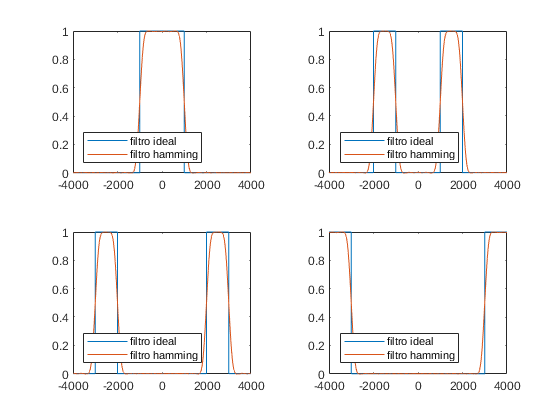

space_fs = bound_fs(1):1:bound_fs(2); % 1 second
%tensors space
filter_fs   = zeros(4,length(space_fs));
filter_time = zeros(4,length(space_fs));
windows     = zeros(4,length(space_fs));

range_fs = (range./(2*pi)).*Fs;

% 4 graphs to be ploted
figure(2)
dt_fs = tiledlayout(2,2);
side =[-1,1]; % positive and negative side of the spectra
for n=2:1:5
    %index in space
    for m=side % negative, positve side
        start_filter = find(space_fs == interp1(space_fs,space_fs,m*range_fs(n-1),'nearest'));
        end_filter   = find(space_fs == interp1(space_fs,space_fs,m*range_fs(n),'nearest'));
        %4d tensor of filters, n-1 acces to layer of tensor.
        filter_fs(n-1,min(start_filter,end_filter):max(start_filter,end_filter)) = 1;
    end
    %time signal of square filter
    filter_time(n-1,:) = real(ftot(filter_fs(n-1,:)));
    %in this case time signal is centered at 0 so 45 coeff means -22,0,22
    middle      = (length(space_fs))/2;
    left        = int32((middle-Coeff/2));
    right       = int32((middle+Coeff/2));
    %inserting hamming filtering
    windows(n-1,left:right) = hamming(Coeff+1)';
    %convolution
    windows(n-1,:) = windows(n-1,:).*filter_time(n-1,:);
    %normalization
    windows(n-1,:) = real(ttof(windows(n-1,:)))/max(real(ttof(windows(n-1,:))));
    %plotting stuff
    nexttile
    plot(space_fs,filter_fs(n-1,:));
    hold on;
    plot(space_fs,windows(n-1,:));
    legend({'filtro ideal','filtro hamming'},'Location','southwest')
    hold off;
end

## Lectura de Audio

figure(7)
[y, audioFS] = audioread("Audios/grape-juice.wav");

Ajustamos el sample rate para garantizar los 8000 samples/sec

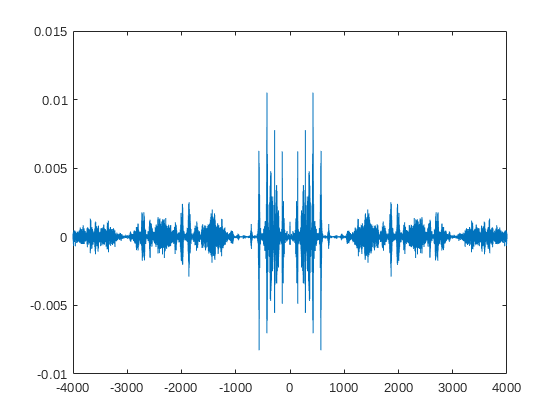

s_down_resample = resample(y, Fs, audioFS);
m_t = s_down_resample(1:(Fs+1)); %cut one second final message signal
m_t_f = real(ftot(m_t)); 
plot(space_fs,m_t_f);

## Aplicacion de filtros en audio 

Simplmente queda como la multiplicacion en frecuencia de las dos señales. 

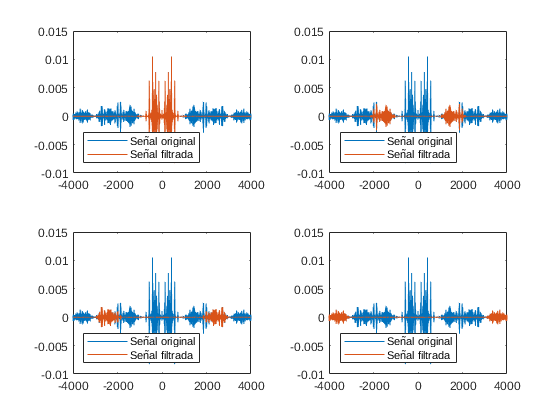

figure(4)
filtered_signals = [m_t_f m_t_f m_t_f m_t_f]';
dt_filtered = tiledlayout(2,2);

for n=1:1:4
    filtered_signals(n,:) = filtered_signals(n,:).*windows(n,:);
    %plotting stuff
    nexttile
    plot(space_fs,m_t_f);
    hold on;
    plot(space_fs,filtered_signals(n,:));
    legend({'Señal original','Señal filtrada'},'Location','southwest')
    hold off;
end

## Conversion y comparación en tiempo

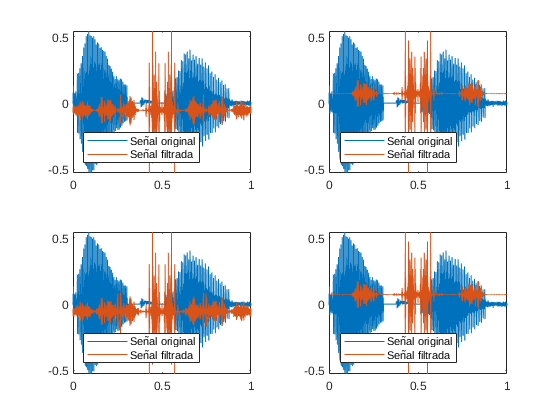

figure(5)
filtered_time = real (ftot(filtered_signals));
dt_filtered_time = tiledlayout(2,2);
time  = 0:1/Fs:1;

for n=1:1:4
    filtered_time(n,:) = rescale(filtered_time(n,:),min(m_t),max(m_t));
    %plotting stuff
    nexttile
    plot(time,m_t);
    hold on;
    plot(time,filtered_time(n,:));
    legend({'Señal original','Señal filtrada'},'Location','southwest')
    hold off;
end